% clear ;

## RSSD Algorithm

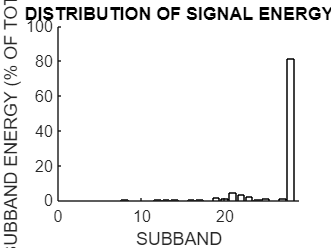

%process complete signal to check for sustained oscillation dominated
%frequency for complete test duration
% 1024 samples best suited for our case where 1512 samples taken for 152 seconds test duration
%% RSSD Parameter
r1=3;
J1=27;
x_sig=x_phase(128:1151,1); % tested and this number is fixed as optimum for finding data analysis for signal capture 
[y1,y2,w1,Q1] = myemd(x_sig);

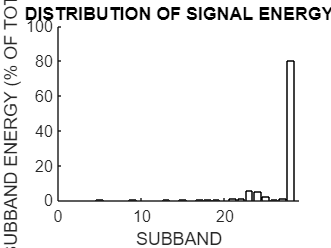

e =     0.5093    0.4422    0.0983    0.0330    0.9653    0.7967    0.1345    0.1789    1.1187    0.3898    0.4332    0.4971    2.3566    0.4462    1.1429    0.6449    1.5806    1.0044    1.1049    0.3426    4.2353    5.0594   21.1718   19.4294    8.3205    1.1396    3.3414  313.2093


% energy in each sub-band (J=27)
e=PlotEnergy(w1)

fs=10;
if Q1<5
    J1=22;
end
% Center freq of each sub-band
fc=tqwt_fc(Q1,r1,J1,fs);
% store centre freq and its energy in matrix hr_test
hr_test=zeros(2,J1);
hr_test(1,:)=fc;
hr_test(2,:)=e(1,1:J1);
%find out the HR indices fundamental
% frequency sorted based on the sub-band energy 
% frequencies arranged in descending order
hr_test_1=hr_test(:,(hr_test(1,:)>1));
hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65))

hr_test_1 =     1.6105    1.5279    1.4495    1.3752    1.3047    1.2378    1.1743
    4.2353    5.0594   21.1718   19.4294    8.3205    1.1396    3.3414


[~,esort]=sort(hr_test_1(2,:),'descend');
fc_hr_1=hr_test_1(1,esort);

% find out the HR indices first harmonic range 
hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
[~,esort]=sort(hr_test_2(2,:),'descend');
fc_hr_2=hr_test_2(1,esort)

fc_hr_2 =     2.4539    2.2087    3.0290    2.0954    2.5865    2.3280    2.7263    2.8737    3.1928


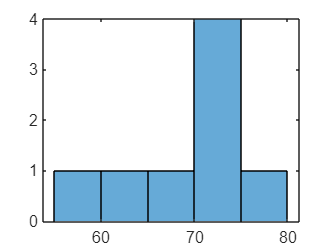


% freq padding if atleast three frequencies are not available 
if length(fc_hr_1)==2
    fc_hr_1(3)=fc_hr_1(1);
elseif length(fc_hr_1)==1
    fc_hr_1(2)=fc_hr_1(1);
    fc_hr_1(3)=fc_hr_1(1);
end
if length(fc_hr_2)==2
    fc_hr_2(3)=fc_hr_2(1);
elseif length(fc_hr_2)==1
    fc_hr_2(2)=fc_hr_2(1);
    fc_hr_2(3)=fc_hr_2(1);
end
if isempty(fc_hr_1)
    fc_hr_1=fc_hr_2./2;
end

x_heart_radar_1=round(fc_hr_1(1:3),2);
% factor 51.2 = 512 pt FFT=10 Hz sampling rate
x_heart_radar_index1=round(x_heart_radar_1.*51.2);
x_heart_radar_2=round(fc_hr_2(1:3),2);
x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
index_hr(1,1:3)=x_heart_radar_index1;
index_hr(1,4:6)=x_heart_radar_index2;
%Find the best representative of frequency in the basic and
%first harmonic top three enrgy values
h=histogram(index_hr(1,:),'BinWidth',5);

[~,idxh]=sort(h.Values,'descend');
index_radar=h.BinEdges(idxh(1))+3;%center of histogram width
               
               

## HR harmonic values estimation through RSSD

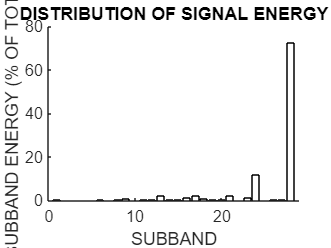

ix0=round(60*512/(fs*60))+3;
Nr=length(x_phase); %% 
Nchirp=512;  %% equivalent to 512*100msec = 52sec
init_chirp = 1;
est_window=10; %% equivalent to 10*100msec= 1sec
noofestimates = round((Nr - Nchirp)/est_window);
ihh=zeros(noofestimates,6);
for p = 1:noofestimates
    end_chirp = init_chirp+Nchirp-1;
    x_sig=x_phase(init_chirp:end_chirp);
    init_chirp= p*est_window +1;
    [y1,y2,w1] = myemd_sec(x_sig,Q1);
    e=PlotEnergy(w1);
    fc=tqwt_fc(Q1,r1,J1,fs);
    hr_test=zeros(2,J1);
    hr_test(1,:)=fc;
    hr_test(2,:)=e(1,1:J1);
    %find out the HR indices fundamental
    hr_test_1=hr_test(:,(hr_test(1,:)>1));
    hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65));
    [~,esort]=sort(hr_test_1(2,:),'descend');
    fc_hr_1=hr_test_1(1,esort);
    
    %first harmonic range check index
    hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
    hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
    [~,esort]=sort(hr_test_2(2,:),'descend');
    fc_hr_2=hr_test_2(1,esort);
    if length(fc_hr_1)==2
        fc_hr_1(3)=fc_hr_1(1);
    elseif length(fc_hr_1)==1
        fc_hr_1(2)=fc_hr_1(1);
        fc_hr_1(3)=fc_hr_1(1);
    end
    if length(fc_hr_2)==2
        fc_hr_2(3)=fc_hr_2(1);
    elseif length(fc_hr_2)==1
        fc_hr_2(2)=fc_hr_2(1);
        fc_hr_2(3)=fc_hr_2(1);
    end
    if isempty(fc_hr_1)
        fc_hr_1=fc_hr_2;
    end
    
    x_heart_radar_1=round(fc_hr_1(1:3),2);
    x_heart_radar_index1=round(x_heart_radar_1.*51.2);
    x_heart_radar_2=round(fc_hr_2(1:3),2);
    x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
    ihh(p,1:3)=x_heart_radar_index1;
    ihh(p,4:6)=x_heart_radar_index2;
end

%Storing the HR indexes including Hexoskin
x_heart = readmatrix("C:\Users\Anuradha\Desktop\RA_Maori Vital Sign Study\Data Collection Folder\Participant 1\HR_Hex_Data_P1.xlsx")

x_heart =     86    83    85    88    86    84    82    90
    86    84    85    88    85    84    82    90
    87    84    84    87    84    83    83    90
    86    84    84    87    84    81    83    89
    85    84    84    85    85    81    84    89
    85    85    84    85    86    82    84    89
    86    85    84    84    86    82    85    87
    87    84    84    84    85    81    85    86
    87    84    84    85    85    81    85    86
    86    83    85    85    85    81    85    85


hr_hex=x_heart(13:12+noofestimates,1);
hr_hex_ind=round(hr_hex*512/600);
hr_ind_cpm=ihh;
hr_ind_cpm(:,7)=index_radar;
hr_ind_cpm(:,8)=hr_hex_ind;
%     f2 = fullfile(filepath,"hr_radar_index.xlsx");
%     writematrix(hr_ind_cpm,f2);

## HUA Algorithm

index_hr = hr_ind_cpm;
n=index_hr(1,7)

n = 73

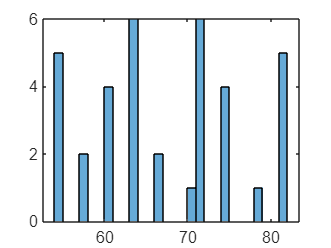

hr_ind_val=zeros(69,1);
index_test=zeros(3,6);
for i=1:63
    h=histogram(index_hr(i:i+5,1:6),'BinWidth',1);
    x=h.BinEdges(h.BinCounts>0);
    y=h.BinCounts(h.BinCounts>0);
    x=x(x<=n+8);
    y=y(x<=n+8);
    x=x(x>=n-6);
    y=y(x>=n-6);
    index_test(2*i-1,1:length(x))=x;
    index_test(2*i,1:length(y))=y;  
end


for i=1:63    
   [~,freq_index_chk]=max(index_test(2*i,:));
   [~,freq_index]=min(abs(index_test(2*i-1,:)-n));
   if i==21
       [maxval,mafid]=mode(hr_ind_val(i-20:i-1,1));
   end
 
   if freq_index_chk<freq_index 
       if  i>20 && mafid>=12 
           [~,indx]=min(abs(index_test(2*i-1,1:6)-maxval));
           hr_ind_val(i,1)=index_test(2*i-1,indx);

       elseif (abs(index_test(2*i-1,freq_index_chk)-n)==3)&& (index_test(2*i-1,freq_index_chk)<60)
           hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk)+4;

       else
           hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk);
       end
   elseif (freq_index_chk>=freq_index)         
        if i>20 && mafid>=12
           [~,indx]=min(abs(index_test(2*i-1,1:6)-maxval));
           hr_ind_val(i,1)=index_test(2*i-1,indx);
        elseif length(nonzeros(index_test(2*i-1,:)))>freq_index_chk
             hr_ind_val(i,1)=round(mean(index_test(2*i-1,freq_index:freq_index+1)));
        else
            hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk);
        end
   end  
end    

## HR Comparision


hr_radar=round(hr_ind_val.*(60*10/512));
for i=2:69
    if abs(hr_radar(i,1)-hr_radar(i-1,1))>=10
        hr_radar(i,1)=round(mean(hr_radar(i-1:i,1)));
    end
end

hr_hex = round(index_hr(:, 8).*(60*10/512));
hr_radar_avg=floor(mean(hr_radar))

hr_radar_avg = 82

hr_hex_avg=floor(mean(hr_hex))

hr_hex_avg = 83